## **Question 2**


$$\min \;Z=\left(\textrm{x1}-3\right)2+\left(\textrm{x2}-3\right)2$$



$$\begin{array}{l}
4x21+9x22\le 36\\
x21+3\mathrm{x2}=3\\
x=\left(\mathrm{x1},\mathrm{x2}\right)\in X\equiv \left\lbrace x:\mathrm{x1}\ge -1\right\rbrace 
\end{array}$$


Part 1: Sketch (manually or via MATLAB) the feasible region and the contours of the objective function. Identify the optimum graphically.

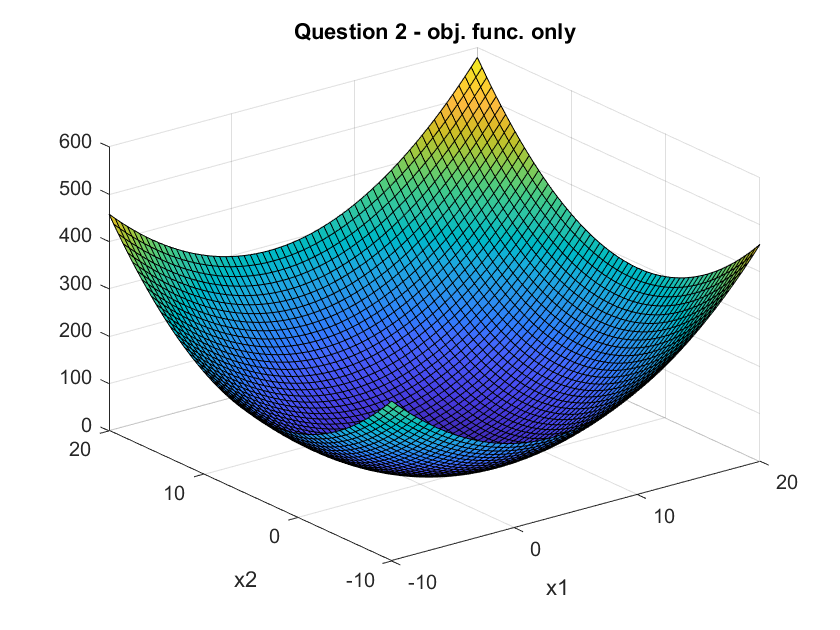

[x,y] = meshgrid(-10:0.5:20,-10:0.5:20);

MyFunc = power((x-3),2) + power((y-3),2);

const1 = 4*power(x,2) + 9*power(y,2) -36;
const2 = power(x,2) + 3*power(y,2) - 3;
const3 = x + 1;
const4 = y + 1;

%%func
surf(x,y, MyFunc)

title('Question 2 - obj. func. only')
xlabel('x1')
ylabel('x2')

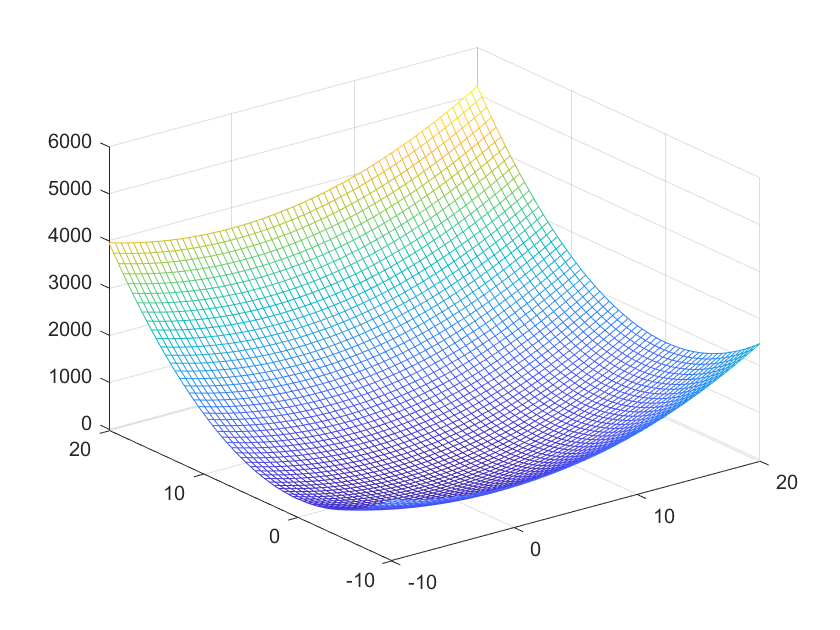


mesh(x,y,const1,const2)

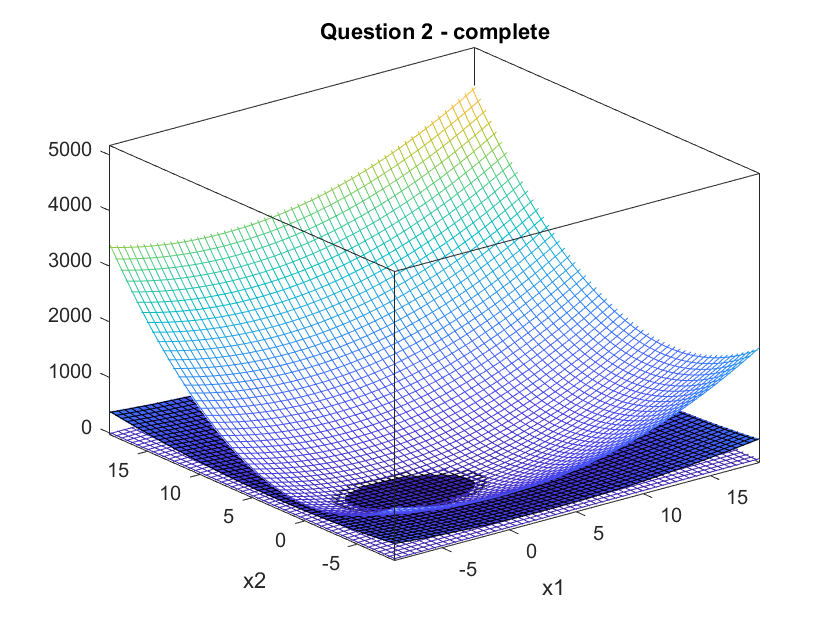


%%contours
contour(x,y,MyFunc, const1,const2,const3,const4)

hold on 
surf(x,y, MyFunc)

mesh(x,y,const1,const2)

mesh(x,y,const3,const4)
hold off

title('Question 2 - complete')
xlabel('x1')
ylabel('x2')

xlim([-8.6 18.7])
ylim([-8.6 18.6])
zlim('auto')
view([-38 29])

Part 2: Repeat part 1 by replacing minimization with maximization in the problem statement.

x = 4.5

x2 = -0.5

z = 47.25

### **Question 3**


$$\mathrm{min}f\left(x\right)=x+\frac{1}{x}$$


Part 1: Use MATLAB to generate 2D and 3D plots of f(x) in the range [−10, 10]. Analytically calculate all stationary points and determine whether they are local min/max or inflection point. 

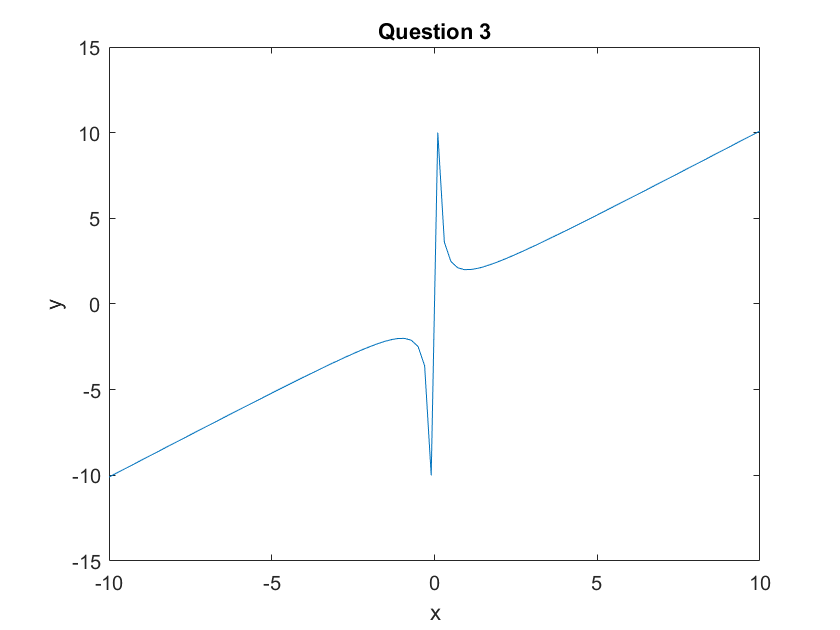

x = linspace(-10,10,100);

MyFunc2 = x + 1./x;

plot(x,MyFunc2)

title('Question 3')
xlabel('x')
ylabel('y')

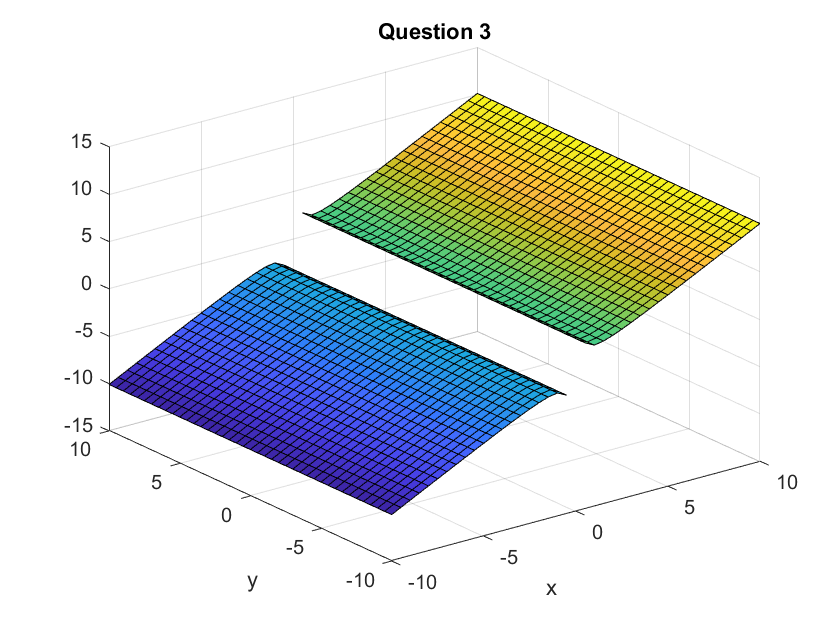


[x,y] = meshgrid(-10:0.5:10,-10:0.5:10);

MyFunc2 = x + 1./x;

surf(x,y,MyFunc2)

title('Question 3')
xlabel('x')
ylabel('y')

- [0,0] is inflection point, [0,-10] and [-10,-10] are global min. Global max occurs on [0,10] and [10,10]. Locam max is, [-0.9,-2.0] and [1.1,2.0] is local min.

- Global optimum solution is -10, global optimum solution does occurs on stationary point.